# Sheet Music Reader Live Script

#### Ray Tang, Ethan Mornement, Jordan Baker, Joshua Politylo

## 1.0 - Introduction

Our live script aims to deliver a computational solution to the problem of converting sheet music to sound.

Our project is essentially a function that takes a specified sheet music png file as input, and then outputs a wav file that should approximately correspond to the input file.

This synthesises aspects from both the image and sound processing topics studied in this unit, extending upon the image processing aspect by automatically reading the notes in a music sheet (recognizing musical notes and determining pitch/position in song) and rendering this information as sound.

Our script has limitations in that it cannot play flats and sharps, and that it only takes pre-processed types of sheet music of specific properties. 

Thus, if you are familiar with the following example songs, they may sound differently to how they normally sound. This is because of the aforementioned inability to play sharps/flats. 

The pacing of the songs may seem slightly off due to the spacing between notes being used as a measure of how long to pause between notes.

## 2.0 - Proof of concept

Run the below command.

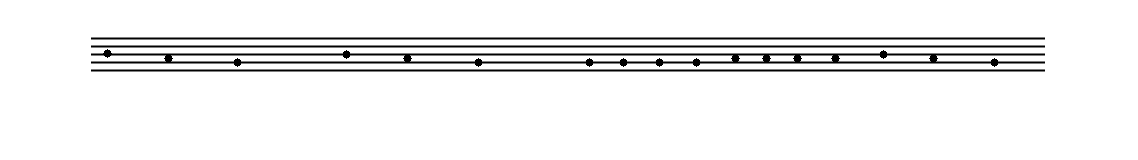

imshow('hotcrossbuns.png')

This is our very first piece of sheet music, a short, simple melody with very little complexity.

Our function is stored in the file create_song.m, and it takes 3 arguments.

arg1 - Sheet music file name (e.g. hotcrossbuns.png)

arg2 - Pace (how fast the notes are played, will be covered further down)

arg3 - Output filename (e.g. hotcrossbuns.wav)

Run the below code section and listen to the wav file. It should sound something reminiscent of hot cross buns.

pace = 0.33;
create_song('hotcrossbuns.png', pace, 'hotcrossbuns.wav');
[y, Fs] = audioread('hotcrossbuns.wav');
sound(y,Fs);

If you wish, you may also navigate to the working folder and verify that there was indeed a hotcrossbuns.wav file created by this command. 

## 3.0 - Features

### 3.1 - Modifying speed

Our function allows you to input a 'pace' parameter, which controls the speed of the output file. A larger pace means a slower song, whilst a lower pace means a lower song.

Compare the tempo of this song

pace = 0.33;
create_song('sans.png', pace, 'sans.wav');
[y, Fs] = audioread('sans.wav');
sound(y,Fs);

To the tempo of this song.

pace = 0.15;
create_song('sans.png', pace, 'sans.wav');
[y, Fs] = audioread('sans.wav');
sound(y,Fs);

Observe how the second song sounds faster. The higher the value of the pace parameter, the slower the song is, whilst the lower the value, the slower the song is. 

### 3.2 - Chords

Our function also has the ability to interpret chords, that is, it can play multiple notes at once. All the examples shown so far have only played one note at a time.

Play the following two songs.

pace = 0.25;
create_song('tetris.png', pace, 'tetris.wav');
[y, Fs] = audioread('tetris.wav');
sound(y,Fs);

pace = 0.25;
create_song('mii.png', pace, 'mii.wav');
[y, Fs] = audioread('mii.wav');
sound(y,Fs);

You should be able to discern that multiple notes are playing at once.

## 4.0 - How it works

### 4.1 - Image Processing Synthesis

Our function works by first reading a png file of sheet music and converting it to a black and white image array: like so

music=imread('hotcrossbuns.png');
%tolerance of 5 - meaning only pixels with a value less than 5 are treated as "black"
music_data = music(:,:,1) <= 5;

This synthesizes image processing techniques covered in this unit, as it imports an external .png file into matlab, and then processes it by converting it from RGB formatting to black and white formatting, whilst also getting rid of any unnecessary features of the image that may not need. 

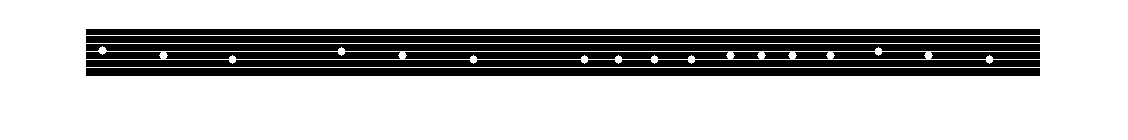

imshow(music_data)

Not any old sheet music will work however, the sheet music must first be pre-processed in order for our function to be able to read it.

#### 4.1.1 - Pre-processing

Observe the following image.

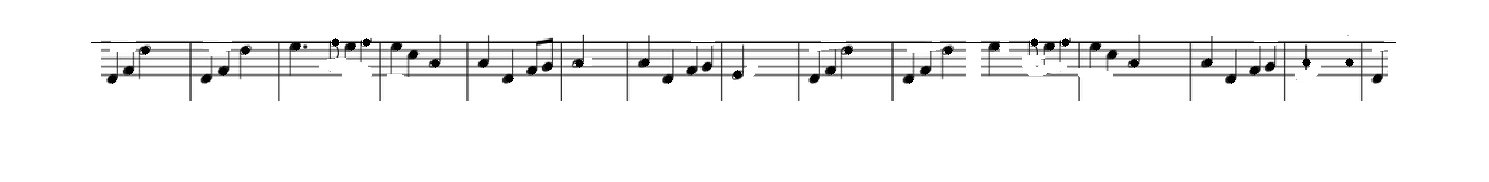

imshow('storm.png')

This file has been preprocessed by eliminating any symbols/tails that are not notes, and going over the important details in pure black pen. Notice how each note has been gone over in black pen, and the very first top stave line is also darker than the others and continues across the entire image.

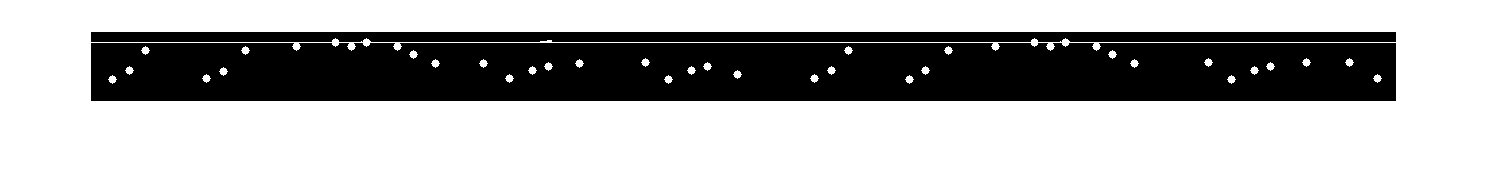

music=imread('storm.png');
%tolerance of 5 - meaning only pixels with a value less than 5 are treated as "black"
music_data = music(:,:,1) <= 5;
imshow(music_data)

This has been shown in more detail here. Note how only the very first stave line and the 'head' of each note has been imported.

One last thing to note of pre-processing, is that each input image must have specific dimensions such that each stave line is approximately 8 pixels away from each other, and each note has a radius of approximately 8 pixels.

The above example converted into a wav file:

create_song('storm.png', pace, 'storm.wav');
[y, Fs] = audioread('storm.wav');
sound(y,Fs);

### 4.2 - Sound Processing Synthesis

#### 4.2.1 - Creating Notes

Our function also synthesizes techniques from the sound processing aspects of this unit by creating an array of the notes on the treble clef staff. This was done by first creating an array of zeroes that would hold all possible note frequencies from C2 (the deep C) to C6 (soprano C). A loop was then used to populate this array with said frequencies, using the formula (taken from [https://en.wikipedia.org/wiki/Piano_key_frequencies](https://en.wikipedia.org/wiki/Piano_key_frequencies)):

Where f(n) is the frequency of the nth piano key.

These frequencies would then be fed into the following formula so as to convert each frequency into its corresponding note.

Where t is an array of values equally spaced from 0 to given pace (the parameter controlling the speed of the song), using a sampling rate of 8192

After this, notes that were not flat or sharp were made and then placed into an array that would hold all the notes from highest pitch to lowest pitch on the treble clef, which could then be rearranged to compose music.

For more details please see the %Creating notes section of create_song.m.

### 4.3 - Image Processing Extension (and more Sound Processing Synthesis)

Our function extends on image processing by its ability to determine individual components of the input file (first stave line and each individual note, as well as timing/distance between each note). 

#### 4.3.1 - Auxilliary Functions

This was done through the use of 3 auxilliary functions.

The first function determines where the first stave line is, and stores the y coordinate of the stave line for later use in determining the pitch of the notes.

The second function determines if a given pixel as a 'note' or not. The definition of a note in this sense is a black pixel that is surrounded by black pixels, and there is a continuous uninterrupted line of black pixels vertically and horizontally adjacent that is large enough (4 pixels long on all sides) to be considered a note. This can be observed as all examples use a radius of 4 pixels for each note.

The third function determines how far (vertically) a given pixel is from the stave line, and then converts this information to an actual note using the previously mentioned array of treble clef notes. 

For more detail please refer to the %Auxilliary functions section of create_song.m.

#### 4.3.2 - Getting Notes

The actual, 'core' part of the function uses these functions as follows:

It first establishes the y-coordinate of the topmost staveline from the first function, to be given to the third function when determining pitch of notes. It also creates an array to be used to store the arrangement of notes that compose the final 'song'.

It then iterates through the given input image data and checks each pixel to see if it is a note or not, using the second function. If it is a note, then the pitch of the note is found using the third function. All notes found in the same column are then added together to produce a new sound - a chord. After a sound has been made, the horizontal distance between the current note and most previously find note/chord is used to determine how long the pause should be between said sounds. This is then added to the previously mentioned 'song' array, and then repeated until the entire song has been completed.

This song array is then scaled so as to avoid peaking, and then written to an output file specified by one of the aforementioned parameters.

For more detail please refer to the %Getting notes section of create_song.m.

## 5.0 - Conclusion

In conclusion, this live script demonstrates the usage of the create_song() function as a computational solution to the novel (to this unit) problem of converting sheet music to sound, synthesizing aspects from sound and image processing, and extending upon aspects of image processing by its ability to identify properties of a song from an image file.